Here are the 5-year temperature averages again.

year = (1955:5:2000)';
y = [ -0.0480; -0.0180; -0.0360; -0.0120; -0.0040;
    0.1180; 0.2100; 0.3320; 0.3340; 0.4560 ];

The standard best-fit line results from using a linear polynomial that meets the least squares criterion. 

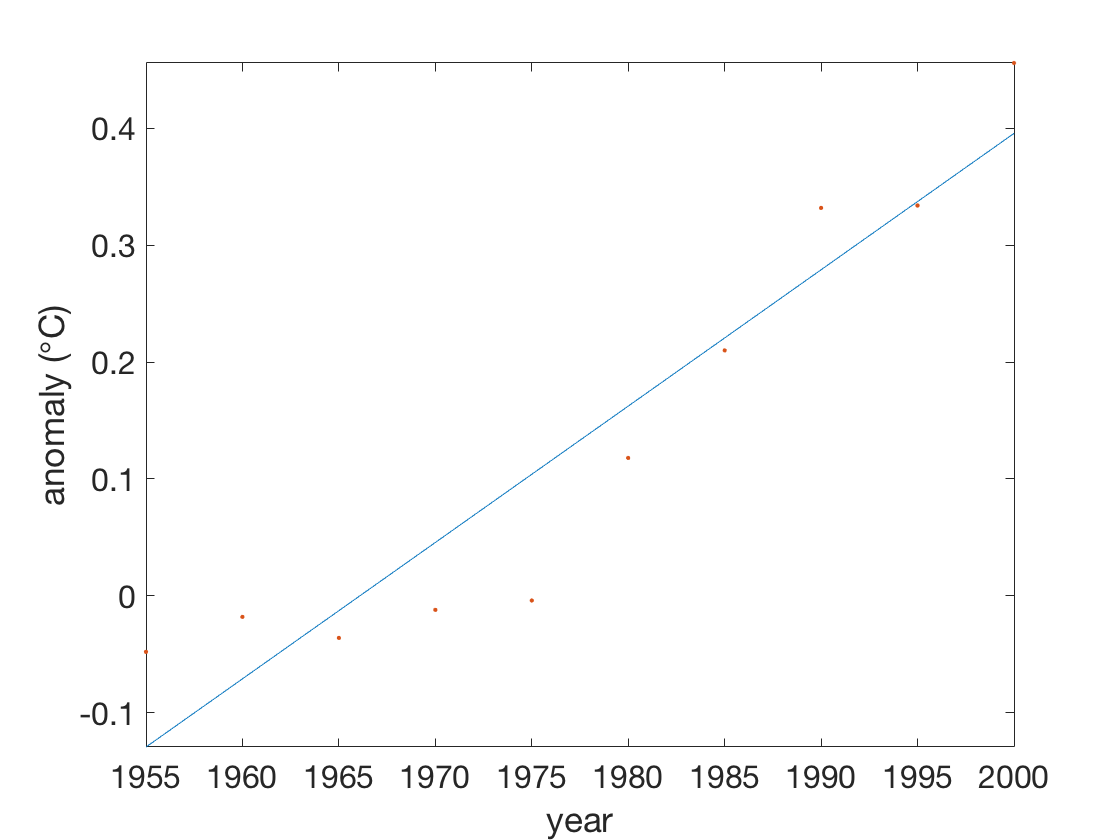

t = year - 1955;             % better matrix conditioning later
V = [ t.^0 t ];    % Vandermonde-ish matrix
c = V\y;
f = @(x) polyval(c(end:-1:1),x-1955);
fplot(f,[1955 2000])
hold on, plot(year,y,'.')
xlabel('year'), ylabel('anomaly ({\circ}C)'), axis tight   % ignore this line

If we use a global cubic polynomial, the points are fit more closely.

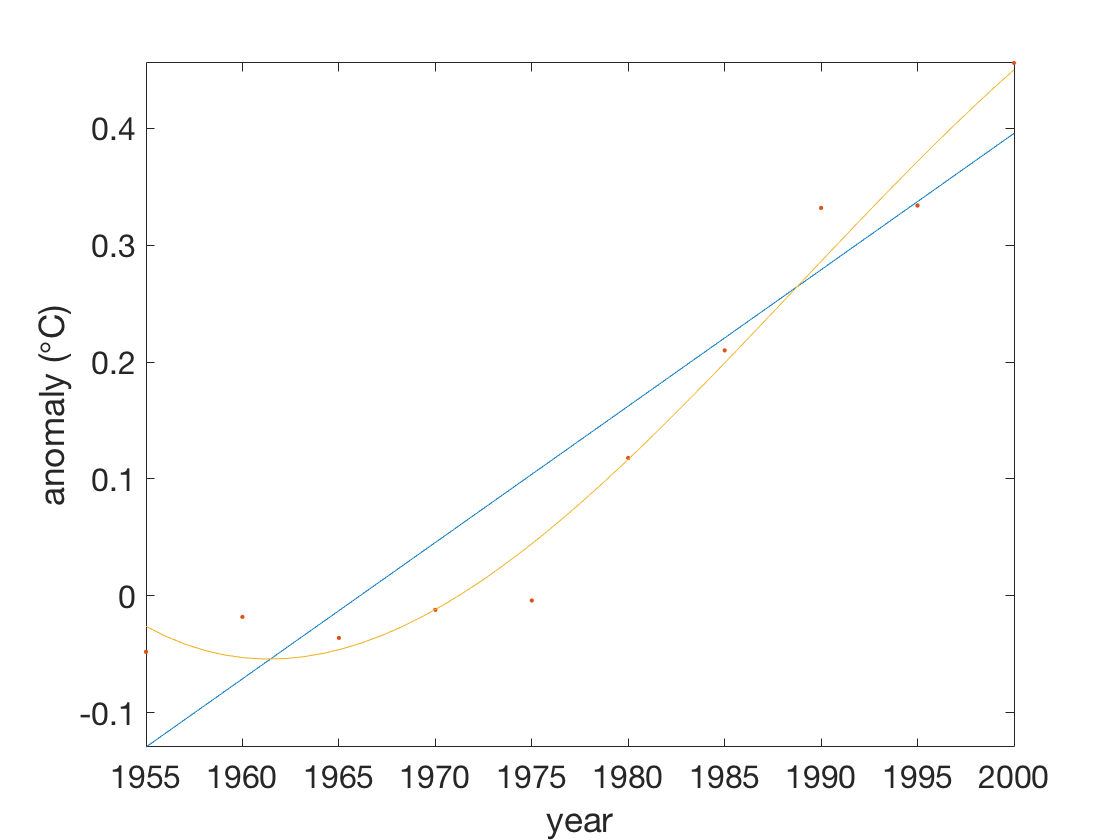

V = [ t.^0 t t.^2 t.^3];    % Vandermonde-ish matrix
c = V\y;   f = @(x) polyval(c(end:-1:1),x-1955);
fplot(f,[1955 2000])

If we were to continue increasing the degree of the polynomial, the residual at the data points would get smaller, but overfitting would increase.